Build a lightly damped plant model (same as notch design example)

s = tf('s');
G = 1/s^2/(s^2+3.77*s+3948);  %Build a plant model with a lightly damped mode
wc = 17;  %Set the crossover frequency - can get any value we want!
a = 0.8;  %Choose these somewhat arbitrarily to get 40 degree PM
b = 6;    %Choose for 40 degree PM

Control design

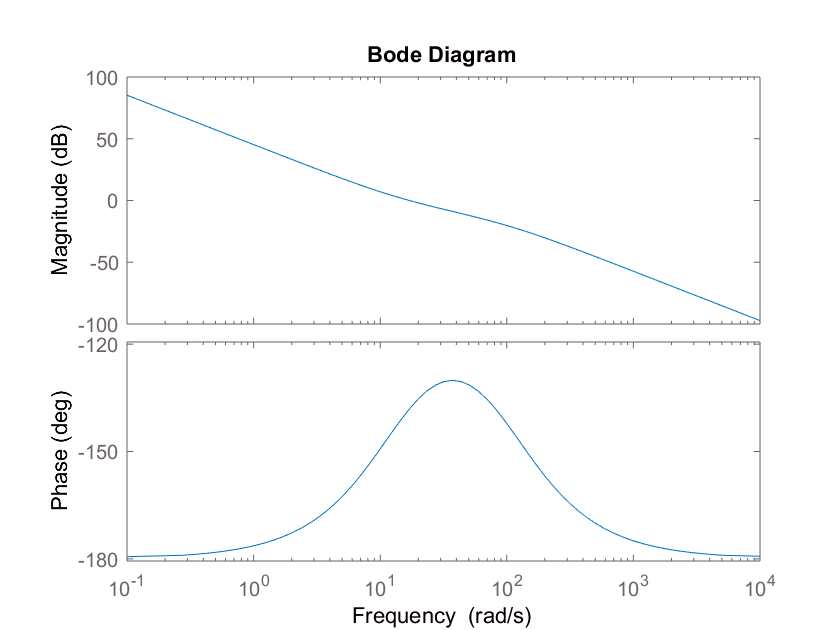

L = (s+a*wc)/s^2/(s+b*wc);  %Build desired loopshape
[mag,phase] = bode(L,wc);  %Find gain adjustment
figure(5)
bode(L/mag)  %The desired loopshape

Now design the controller using inversion

K2 = (s+a*wc)*(s^2+3.77*s+3948)/(s+b*wc)/(s+10*b*wc)^2;

The double pole at (s+10*b*wc) is used to get a proper system

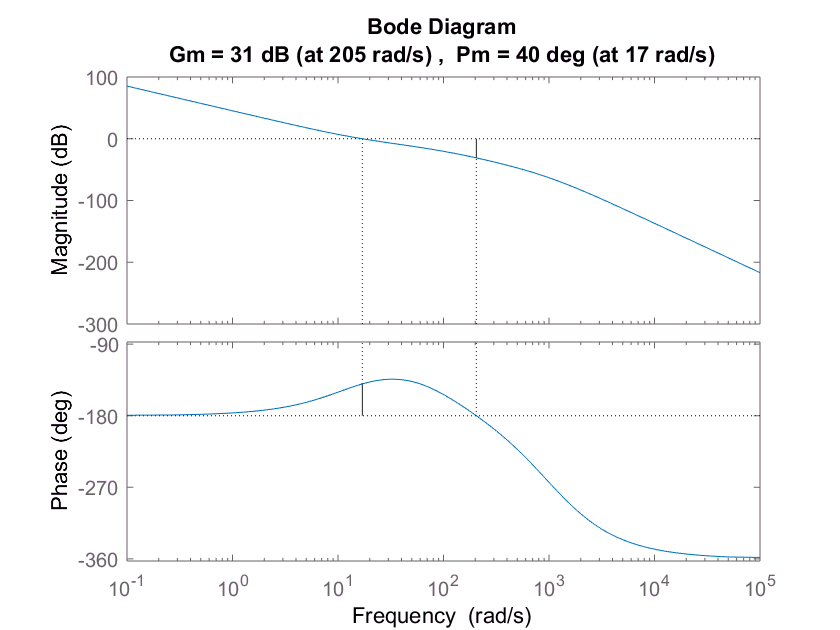

[mag2,phase] = bode(G*K2,wc);  %Find gain adjustment
K2 = K2/mag2;
margin(G*K2)  %We still have a ton of gain margin!

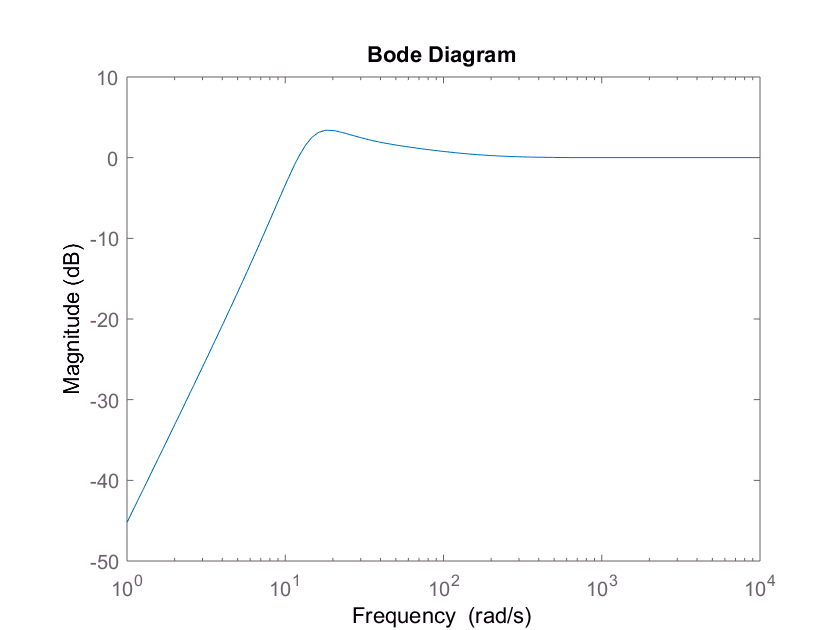

S_I = 1/(1+G*K2);
bodemag(S_I)  %This is the sensitivity function - looks good

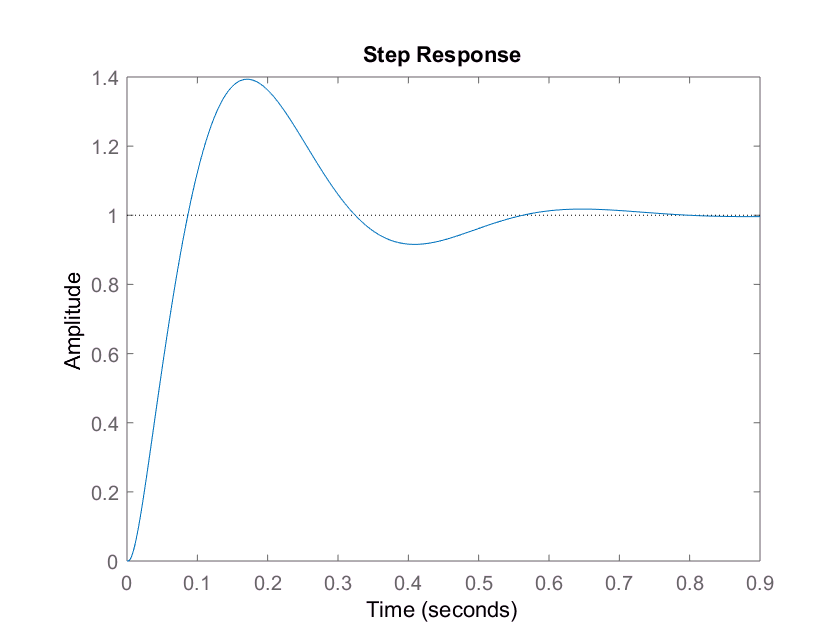

step(feedback(G*K2,1))  %Very fast response

The downside is control usage...this is a typical problem with inverse based designs

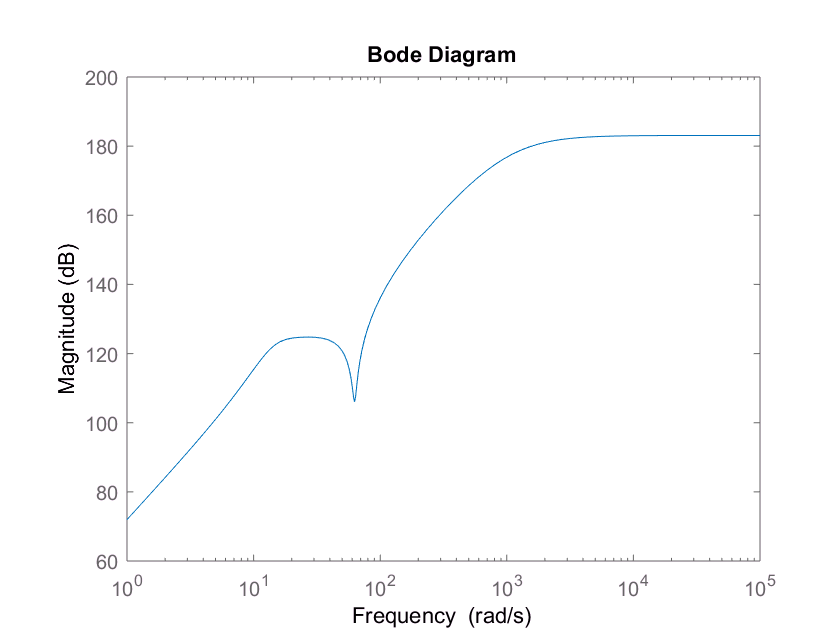

bodemag(K2/(1+G*K2)) %Massive control usage at high frequency

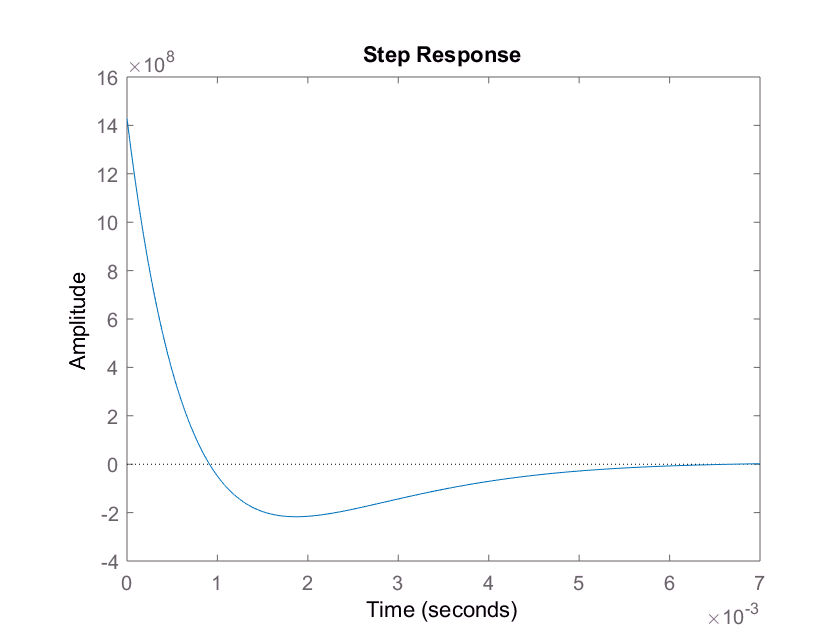

step(K2/(1+G*K2))